clear all

## **TRAIETTORIA CIRCOLARE**

### CONFRONTO RMSE A PARITA' DI RAGGIO E AL VARIARE DELLA FREQUENZA

`RAGGIO 10 mm`

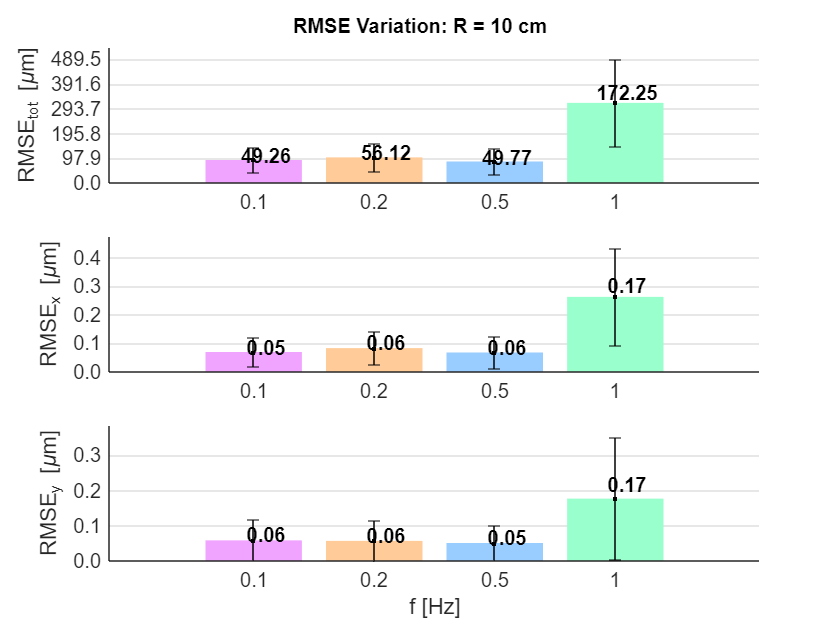

data_r10_t10 = load(['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_robot\cerchio_r10_t10s\data.mat']);
data_r10_t10 = data_r10_t10.data;

data_r10_t5 = load(['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_robot\cerchio_r10_t5s\data.mat']);
data_r10_t5 = data_r10_t5.data;

data_r10_t2 = load(['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_robot\cerchio_r10_t2s\data.mat']);
data_r10_t2 = data_r10_t2.data;

data_r10_t1 = load(['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_robot\cerchio_r10_t1s\data.mat']);
data_r10_t1 = data_r10_t1.data;

% Creazione della struttura per organizzare i dati
data_r10 = struct();

% frequenze
data_r10.freq = [1/10, 1/5, 1/2, 1];

% RMSE e barre di errore totali
data_r10.tot.rmse = [data_r10_t10(1,1), data_r10_t5(1,1), data_r10_t2(1,1), data_r10_t1(1,1)];
data_r10.tot.errori = [data_r10_t10(1,2), data_r10_t5(1,2), data_r10_t2(1,2), data_r10_t1(1,2)];

% RMSE e barre di errore per la componente X
data_r10.x.rmse = [data_r10_t10(2,1), data_r10_t5(2,1), data_r10_t2(2,1), data_r10_t1(2,1)];
data_r10.x.errori = [data_r10_t10(2,2), data_r10_t5(2,2), data_r10_t2(2,2), data_r10_t1(2,2)];

% RMSE e barre di errore per la componente Y
data_r10.y.rmse = [data_r10_t10(3,1), data_r10_t5(3,1), data_r10_t2(3,1), data_r10_t1(3,1)];
data_r10.y.errori = [data_r10_t10(3,2), data_r10_t5(3,2), data_r10_t2(3,2), data_r10_t1(3,2)];

% Titolo e etichette
titolo = 'RMSE Variation: R = 10 mm';
xlabel_text = 'f [Hz]';

% Chiamata della funzione
subPlotRMSEWithErrors(data_r10, titolo, xlabel_text);

`RAGGIO 5 mm`

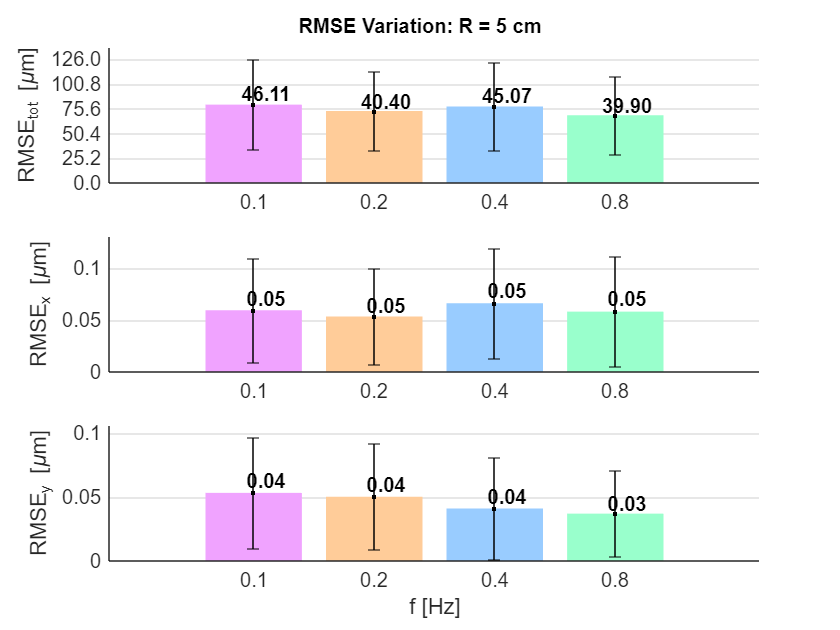

data_r5_t10 = load(['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_robot\cerchio_r5_t10s\data.mat']);
data_r5_t10 = data_r5_t10.data;

data_r5_t5 = load(['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_robot\cerchio_r5_t5s\data.mat']);
data_r5_t5 = data_r5_t5.data;

data_r5_t2_5 = load(['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_robot\cerchio_r5_t2_5s\data.mat']);
data_r5_t2_5 = data_r5_t2_5.data;

data_r5_t1_25 = load(['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_robot\cerchio_r5_t1_25s\data.mat']);
data_r5_t1_25 = data_r5_t1_25.data;

% Creazione della struttura per organizzare i dati
data_r5 = struct();

% definizione dei valori sull'asse x
data_r5.freq = [1/10, 1/5, 1/2.5, 1/1.25]; % in Hz

% RMSE e barre di errore totali
data_r5.tot.rmse = [data_r5_t10(1,1), data_r5_t5(1,1), data_r5_t2_5(1,1), data_r5_t1_25(1,1)];
data_r5.tot.errori = [data_r5_t10(1,2), data_r5_t5(1,2), data_r5_t2_5(1,2), data_r5_t1_25(1,2)];

% RMSE e barre di errore per la componente X
data_r5.x.rmse = [data_r5_t10(2,1), data_r5_t5(2,1), data_r5_t2_5(2,1), data_r5_t1_25(2,1)];
data_r5.x.errori = [data_r5_t10(2,2), data_r5_t5(2,2), data_r5_t2_5(2,2), data_r5_t1_25(2,2)];

% RMSE e barre di errore per la componente Y
data_r5.y.rmse = [data_r5_t10(3,1), data_r5_t5(3,1), data_r5_t2_5(3,1), data_r5_t1_25(3,1)];
data_r5.y.errori = [data_r5_t10(3,2), data_r5_t5(3,2), data_r5_t2_5(3,2), data_r5_t1_25(3,2)];

% Titolo e etichette
titolo = 'RMSE Variation: R = 5 mm';

% Chiamata della funzione
subPlotRMSEWithErrors(data_r5, titolo, xlabel_text);

### CONFRONTO RMSE A PARITA' DI FREQUENZA E AL VARIARE DEL RAGGIO

*Frequenza 0.1 Hz*

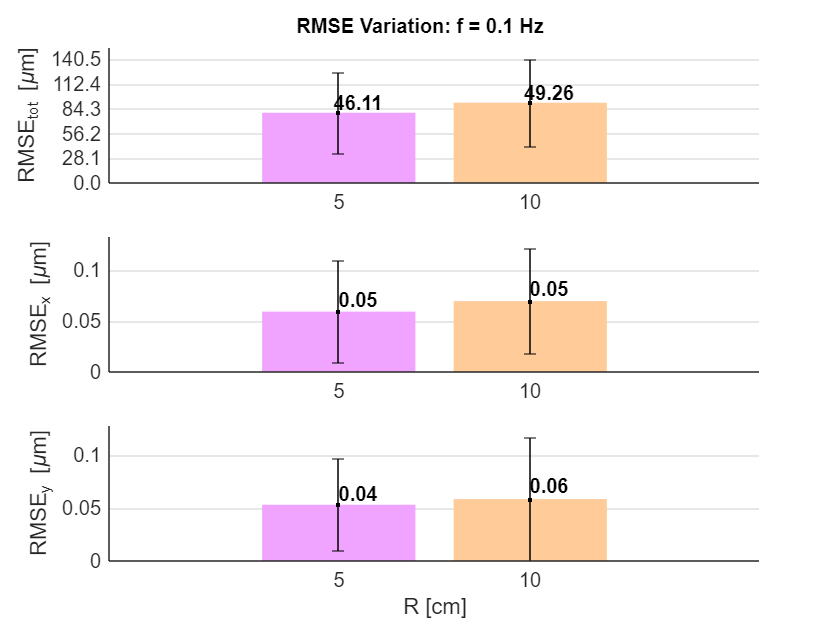

% Dati 

% Creazione della struttura per organizzare i dati
data_f0_1 = struct();

% definizione dei valori sull'asse x
data_f0_1.freq = [5, 10]; % Valori in cm 

% RMSE e barre di errore totali
data_f0_1.tot.rmse = [data_r5_t10(1,1), data_r10_t10(1,1)]; % Valori di RMSE corrispondenti
data_f0_1.tot.errori = [data_r5_t10(1,2), data_r10_t10(1,2)]; % Barre di errore 

% RMSE e barre di errore per la componente X
data_f0_1.x.rmse = [data_r5_t10(2,1), data_r10_t10(2,1)]; % Valori di RMSE corrispondenti
data_f0_1.x.errori = [data_r5_t10(2,2), data_r10_t10(2,2)]; % Barre di errore 

% RMSE e barre di errore per la componente Y
data_f0_1.y.rmse = [data_r5_t10(3,1), data_r10_t10(3,1)]; % Valori di RMSE corrispondenti
data_f0_1.y.errori = [data_r5_t10(3,2), data_r10_t10(3,2)]; % Barre di errore 

% Titolo
titolo = 'RMSE Variation: f = 0.1 Hz';
xlabel_test = 'R [mm]';

% Chiamata della funzione
subPlotRMSEWithErrors(data_f0_1, titolo, xlabel_test);

## TRAIETTORIA OTTO

### CONFRONTO RMSE A PARITA' DI RAGGIO E AL VARIARE DELLA FREQUENZA

`RAGGIO 10 mm`

otto_r10_t10 = load(['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_robot\otto_r10_t10s\data.mat']);
otto_r10_t10 = otto_r10_t10.data;

otto_r10_t5 = load(['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_robot\otto_r10_t5s\data.mat']);
otto_r10_t5 = otto_r10_t5.data;

otto_r10_t2_5 = load(['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_robot\otto_r10_t2_5s\data.mat']);
otto_r10_t2_5 = otto_r10_t2_5.data;

% Creazione della struttura per organizzare i dati
otto_r10 = struct();

% frequenze
otto_r10.freq = [1/10, 1/5, 1/2.5];

% RMSE e barre di errore totali
otto_r10.tot.rmse = [otto_r10_t10(1,1), otto_r10_t5(1,1), otto_r10_t2_5(1,1)];
otto_r10.tot.errori = [otto_r10_t10(1,2), otto_r10_t5(1,2), otto_r10_t2_5(1,2)];

% RMSE e barre di errore per la componente X
otto_r10.x.rmse = [otto_r10_t10(2,1), otto_r10_t5(2,1), otto_r10_t2_5(2,1)];
otto_r10.x.errori = [otto_r10_t10(2,2), otto_r10_t5(2,2), otto_r10_t2_5(2,2)];

% RMSE e barre di errore per la componente Y
otto_r10.y.rmse = [otto_r10_t10(3,1), otto_r10_t5(3,1), otto_r10_t2_5(3,1)];
otto_r10.y.errori = [otto_r10_t10(3,2), otto_r10_t5(3,2), otto_r10_t2_5(3,2)];

% Titolo e etichette
titolo = 'RMSE Variation: R = 10 mm';
xlabel_text = 'f [Hz]';

% Chiamata della funzione
subPlotRMSEWithErrors(otto_r10, titolo, xlabel_text);

Unrecognized function or variable 'otto_r10'.

`RAGGIO 5 mm`

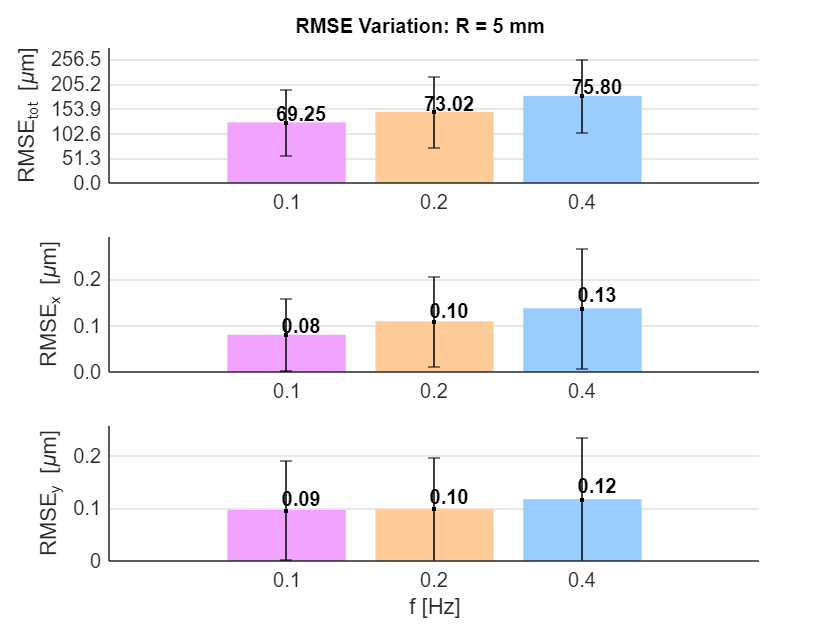

otto_r5_t10 = load(['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_robot\otto_r5_t10s\data.mat']);
otto_r5_t10 = otto_r5_t10.data;

otto_r5_t5 = load(['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_robot\otto_r5_t5s\data.mat']);
otto_r5_t5 = otto_r5_t5.data;

otto_r5_t2_5 = load(['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_robot\otto_r5_t2_5s\data.mat']);
otto_r5_t2_5 = otto_r5_t2_5.data;

% Creazione della struttura per organizzare i dati
otto_r5 = struct();

% frequenze
otto_r5.freq = [1/10, 1/5, 1/2.5];

% RMSE e barre di errore totali
otto_r5.tot.rmse = [otto_r5_t10(1,1), otto_r5_t5(1,1), otto_r5_t2_5(1,1)];
otto_r5.tot.errori = [otto_r5_t10(1,2), otto_r5_t5(1,2), otto_r5_t2_5(1,2)];

% RMSE e barre di errore per la componente X
otto_r5.x.rmse = [otto_r5_t10(2,1), otto_r5_t5(2,1), otto_r5_t2_5(2,1)];
otto_r5.x.errori = [otto_r5_t10(2,2), otto_r5_t5(2,2), otto_r5_t2_5(2,2)];

% RMSE e barre di errore per la componente Y
otto_r5.y.rmse = [otto_r5_t10(3,1), otto_r5_t5(3,1), otto_r5_t2_5(3,1)];
otto_r5.y.errori = [otto_r5_t10(3,2), otto_r5_t5(3,2), otto_r5_t2_5(3,2)];

% Titolo e etichette
titolo = 'RMSE Variation: R = 5 mm';
xlabel_text = 'f [Hz]';

% Chiamata della funzione
subPlotRMSEWithErrors(otto_r5, titolo, xlabel_text);